                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    [https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html)

data = table2array(readtable('../../data/data1/CHID46.csv'));
dpi = data(:,1);
y = data(:,2);
num_pat = 1;

dpi

dpi =     13
    16
    20
    23
    27
    30
    36
    38
    43


h = 0.01;
ti = 0:h:dpi(end); 
init = [10^4 0 10^-3];


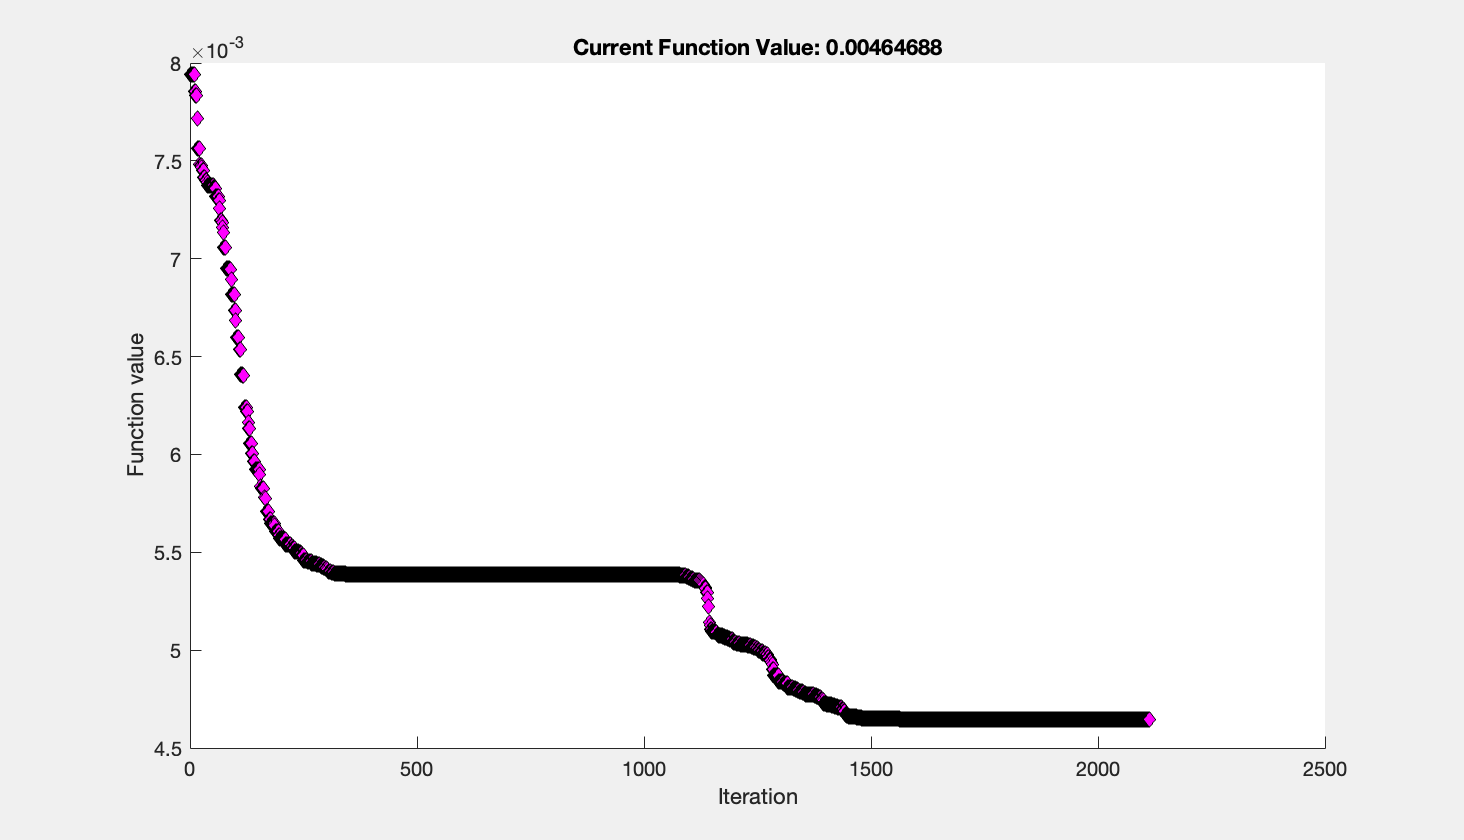


N = 6;
out = zeros(N,8);

x0 = [0.409*10^-6 0.233*10^-6 0.249 0.775 14.5*10^3 0.03 7];

out(1,1) = J(x0, ti, init, h, dpi, y);
out(1,2:end) = x0;


[bp, fval] = best_param(x0,dpi,y,ti,init,h) ;

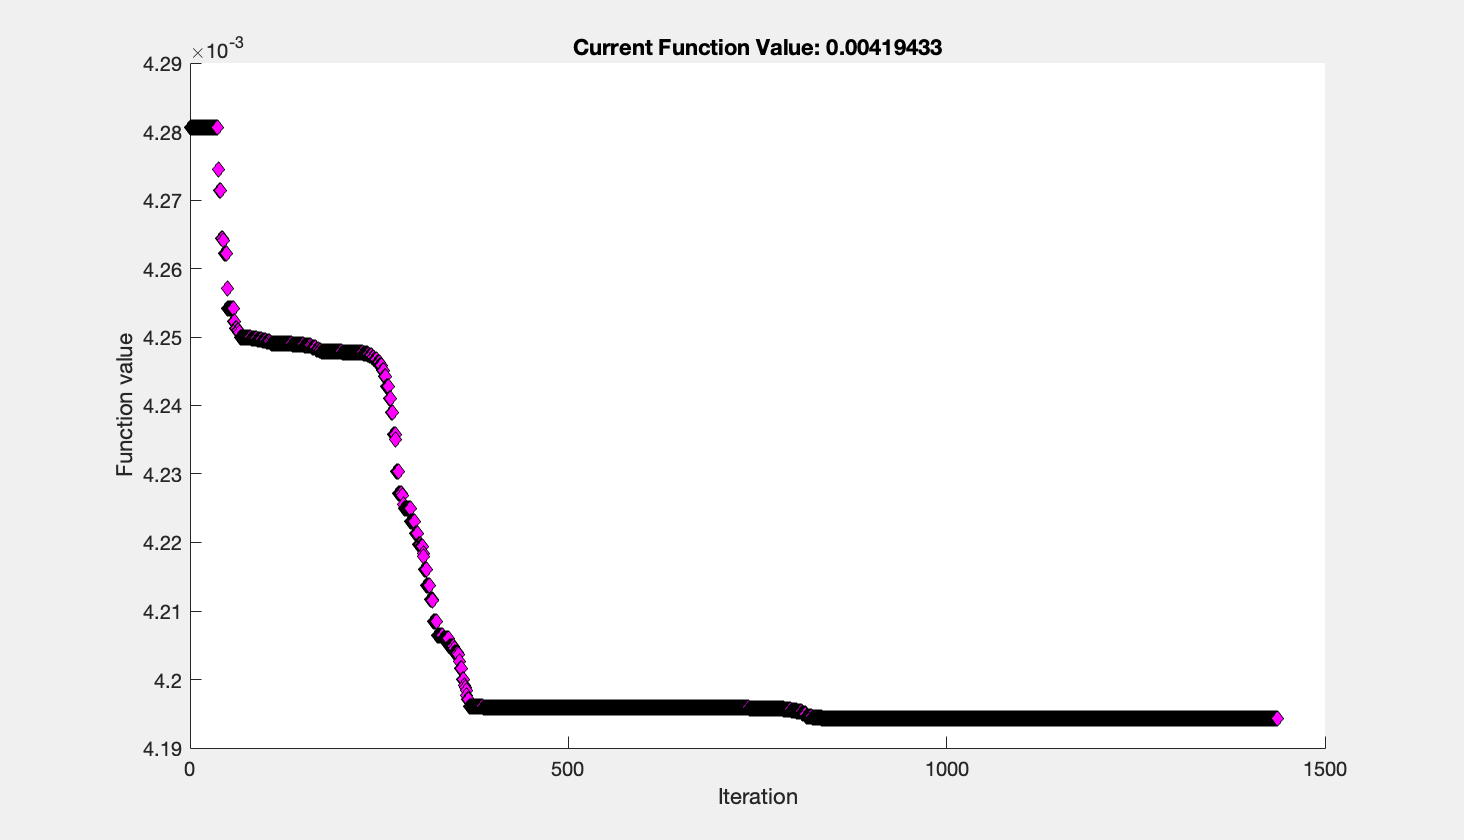

out(2,1) = fval;
out(2,2:end) = bp;

x1 = [2.0209E-7 1.2719E-7 0.41184 1.52453 41085.62299 0.03901 6];
out(3,1) = J(x1, ti, init, h, dpi, y);
out(3,2:end) = x1;

[bp, fval] = best_param(x1,dpi,y,ti,init,h) ;

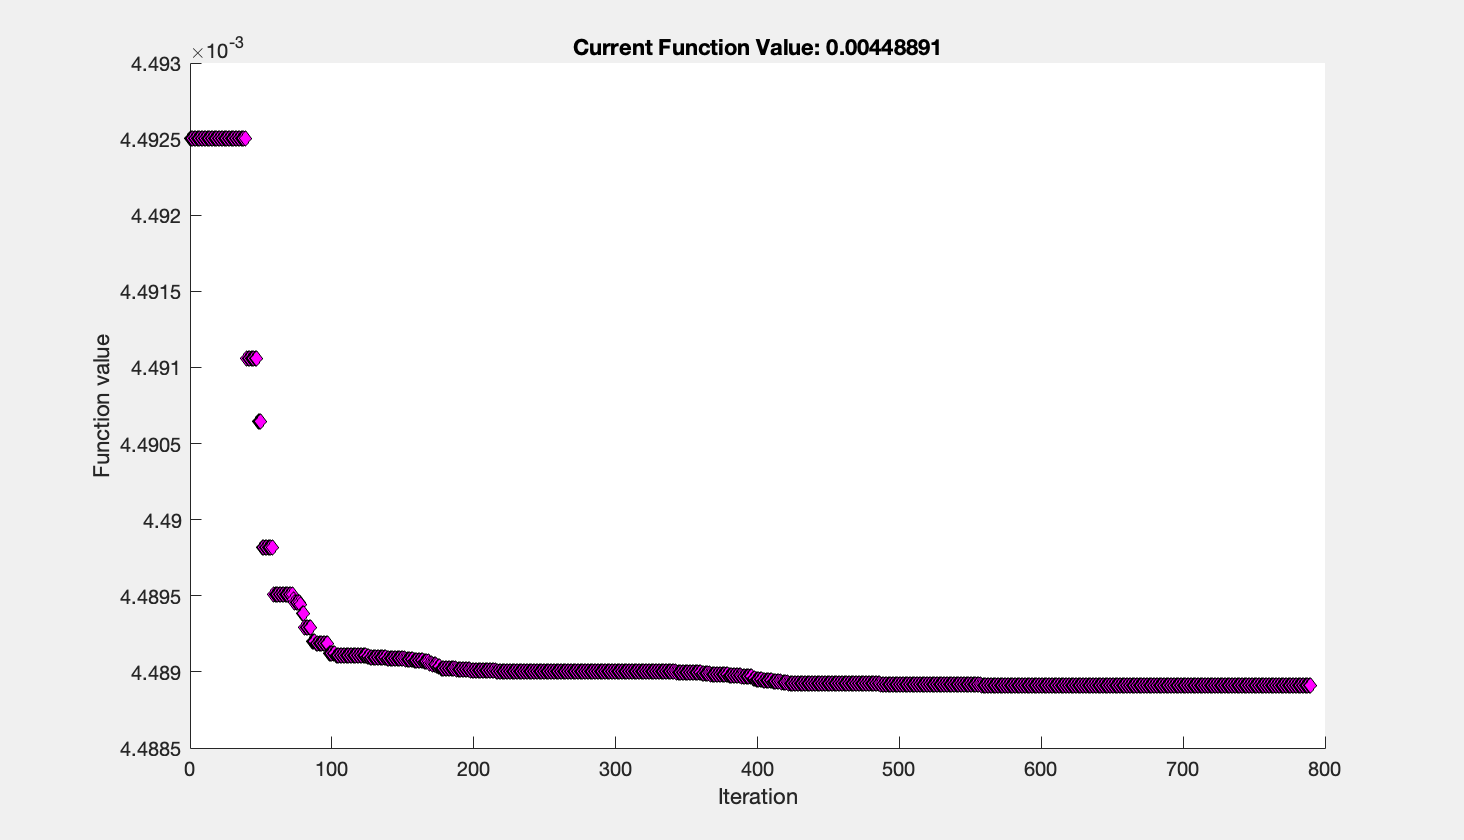

out(4,1) = fval;
out(4,2:end) = bp;

x2 = [2.0273E-7, 1.2499E-7, 1.81286, 1.57038, 42987.62471, 0.03935, 7];
out(5,1) = J(x2, ti, init, h, dpi, y);
out(5,2:end) = x2;

[bp, fval] = best_param(x2,dpi,y,ti,init,h) ;

out(6,1) = fval;
out(6,2:end) = bp;


tb = array2table(out,...
            'VariableNames', ...
            {'J','b0','bi','k','dlt','p','d','tau'},...
            'RowNames',...
            {'paper', 'fminsearch','BM1', 'fminsearch1','BM2', 'fminsearch2'});
writetable(tb, 'results.csv');
tb

tb = 6×8 table
                       J            b0            bi           k        dlt        p         d         tau  
                   _________    __________    __________    _______    ______    _____    ________    ______

    paper           0.007939      4.09e-07      2.33e-07      0.249     0.775    14500        0.03         7
    fminsearch     0.0046469    3.4497e-07    1.5821e-07      1.486    1.2266    29104    0.036181    3.8412
    BM1            0.0042806    2.0209e-07    1.2719e-07    0.41184    1.5245    41086     0.03901         6
    fminsearch1    0.0041943    1.9975e-07     1.265e-07    0.33022    1.5147    40734    0.039136 

%% decay function 

function out=b(t,b0,bi,k,tau)
    if t <= tau
        out = b0;
    else
        out = bi+(b0-bi)*exp(-k*(t-tau));
    end
end


function out = pred(ti,init,params)

    b0 = params(1);
    bi = params(2);
    k = params(3);
    dlt = params(4);
    p = params(5);
    d = params(6);
    tau = params(7);


    f = @(t,x) [d*(init(1)-x(1))-b(t,b0,bi,k,tau)*x(1)*x(3);...
            b(t,b0,bi,k,tau)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-23*x(3) ];    

    [t,xa] = ode45(f,ti,init);
    out = xa(:,3);
 
end

function out=J(params, ti,init,h, dpi,y)

    V = pred(ti,init,params);
    y_hat = log10(V(dpi/h+1));
    out =  1/size(y,1) *sum((y-y_hat).^2);
end 

function [x,fval]=best_param(x0,dpi,y,ti,init,h)
    options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX',1e-7,'MaxFunEvals', 5000,'MaxIter', 5000);
    JJ = @(params) J(params, ti,init,h, dpi,y); 
    [x,fval] = fminsearch(JJ,x0,options);
end 